clear; clc; close all
global b Psi1 Psi2 epsilon1 epsilon2

mew=1000; %kg/m^3
rho=1.225; %air density
c=2; %chord in meters
xf= 0.48*c; 
a=-0.02*c;
t=0.01; %thickness in meters
l=1; %length in meters
omega_h=4; %plunge natural frequency in HZ
omega_a=10; %pitch natural frequency in HZ
b=c/2; %half of the chord length
e=(xf-c/4)/c;

m=c*mew*t*l;
I_alpha=1/12*m*c^2+m*a^2; 
k_plunge= m*(2*pi*omega_h)^2;
k_pitch= I_alpha*(2*pi*omega_a)^2; %converting to rad/s
S=-m*a;
Psi1=0.165;
Psi2=0.335;
epsilon1=0.0445;
epsilon2=0.3;
function [phi]= phi(t, U)
 global b Psi1 Psi2 epsilon1 epsilon2
 x=U*t/b;
 phi = 1-Psi1*exp(-x*epsilon1)-Psi2*exp(-x*epsilon2);
end
function Phi_dot = Phi_dot(t, U)
 global b Psi1 Psi2 epsilon1 epsilon2
    Phi_dot = (U/b) * ( ...
        Psi1*epsilon1*exp(-epsilon1*U*t/b) + ...
        Psi2*epsilon2*exp(-epsilon2*U*t/b));
end

%assuming starting from rest so IC=0


%loop parameters
du=0.01; %m/s
error_margin=1e-7;
Umin=0.1;
Umax=100; %m/s

W1_W = []; d1_W = []; W2_W = []; d2_W= [];
Urange = Umin:du:Umax ;
for U = Urange
t=0;
Phi0=phi(0,U);
Phi_dot0=Phi_dot(0, U);

% Mass matrix
M = [
    m + rho*pi*b^2, ...
    S - rho*pi*b^2*(xf - c/2);
    S - rho*pi*b^2*(xf - c/2), ...
    I_alpha + rho*pi*b^2*((xf - c/2)^2 + b^2/8)
];

% Damping matrix
C = rho*pi*U*c * [
    Phi0, ...
    c/4 + Phi0*(3*c/4 - xf);

    -e*c*Phi0, ...
    (3*c/4 - xf)*(c/4 - e*c*Phi0)
];

% Stiffness matrix
K = [
    k_plunge + rho*pi*U*c*Phi_dot0, ...
    rho*pi*U*c*(U*Phi0 + (3*c/4 - xf)*Phi_dot0);

    -rho*pi*U*e*c^2*Phi_dot0, ...
    k_pitch - rho*pi*U*e*c^2*(U*Phi0 + (3*c/4 - xf)*Phi_dot0)
];

% Wagner lag-state coupling matrix
W = 2*rho*pi*U^3 * [
    -Psi1*epsilon1^2/b, ...
    -Psi2*epsilon2^2/b, ...
    Psi1*epsilon1*(1 - epsilon1*(1 - 2*e)), ...
    Psi2*epsilon2*(1 - epsilon2*(1 - 2*e));

    e*c*Psi1*epsilon1^2/b, ...
    e*c*Psi2*epsilon2^2/b, ...
    -e*c*Psi1*epsilon1*(1 - epsilon1*(1 - 2*e)), ...
    -e*c*Psi2*epsilon2*(1 - epsilon2*(1 - 2*e))
];

B=[1 0; 1 0; 0 1; 0 1;];
G=[-epsilon1*U/b 0 0 0; 0 -epsilon2*U/b 0 0; 0 0 -epsilon1*U/b 0; 0 0 0 -epsilon2*U/b;];
Q = [
    -M\C, -M\K, -M\W;
    eye(2), zeros(2,2), zeros(2,4);
    zeros(4,2), B, G
];

D = eig(Q);
[D_imag,index] = sort(imag(D),'ascend');
D_sort = D(index,:);
W1_W = [W1_W, abs(D_sort(7))]; d1_W = [d1_W,-real(D_sort(7))/abs( D_sort(7))];
W2_W = [W2_W, abs(D_sort(8))]; d2_W = [d2_W,-real(D_sort(8))/abs( D_sort(8))];
end

%need to find where the first eigenvalue crosses into the right half plane
%ie. where the damping ratio becomes negative. 
ind=1;
running=true;
double mode;
while running
    if d1_W(1,ind)<=0; running=false; mode=1; break; end
    if d2_W(1,ind)<=0; running=false; mode=2;break; end
    ind=ind+1;
end
Uflutter=Urange(1,ind)

Uflutter = 82.9500

flutterfrequency=0;
if mode==1;flutterfrequency=W1(ind);end
if mode==2;flutterfrequency=W2_W(ind);end
frequency=flutterfrequency/2/pi %converting to HZ

frequency = 7.2531

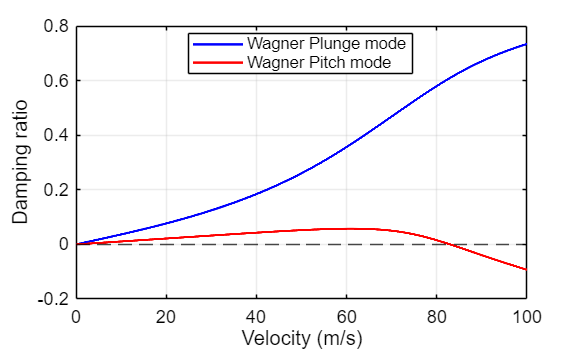


% Figure 1: Damping ratio
fig1 = figure('Color', 'white');
ax1 = axes(fig1);

plot(ax1, Urange, d1_W, 'b-', Urange, d2_W, 'r-', 'LineWidth', 1.5);
yline(ax1, 0, 'k--');

xlabel(ax1, 'Velocity (m/s)', 'Color', 'black');
ylabel(ax1, 'Damping ratio', 'Color', 'black');
lgd=legend(ax1, 'Wagner Plunge mode', 'Wagner Pitch mode', 'Location', 'best');
lgd.Color = 'white';
lgd.EdgeColor = 'black';  % Optional: black border
lgd.TextColor = 'black';
grid(ax1, 'on');
ax1.Color = 'white';
ax1.XColor = 'black';
ax1.YColor = 'black';
ax1.GridColor = [0.7 0.7 0.7];
ax1.FontSize = 11;
ax1.Box = 'on';


% Figure 2: Modal frequency
fig2 = figure('Color', 'white');
ax2 = axes(fig2);

plot(ax2, Urange, W1_W/2/pi, 'b-', Urange, W2_W/2/pi, 'r-', 'LineWidth', 1.5);

xlabel(ax2, 'Velocity (m/s)', 'Color', 'black');
ylabel(ax2, 'Modal frequency (Hz)', 'Color', 'black');
lgd=legend(ax2, 'Wagner Plunge mode', 'Wagner Pitch mode', 'Location', 'best');
lgd.Color = 'white';
lgd.EdgeColor = 'black';  % Optional: black border
lgd.TextColor = 'black';
grid(ax2, 'on');
ax2.Color = 'white';
ax2.XColor = 'black';
ax2.YColor = 'black';
ax2.GridColor = [0.7 0.7 0.7];
ax2.FontSize = 11;
ax2.Box = 'on';


% Export figures
exportgraphics(fig1, 'figure3.png', 'BackgroundColor', 'white', 'Resolution', 300);

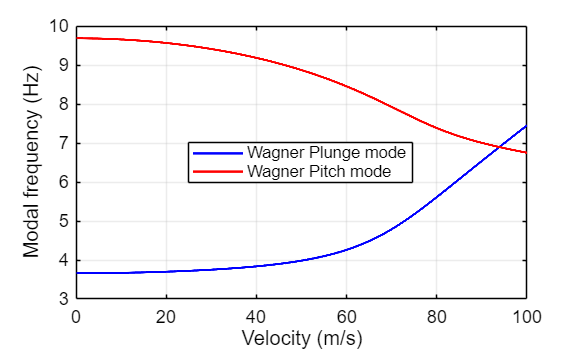

exportgraphics(fig2, 'figure4.png', 'BackgroundColor', 'white', 'Resolution', 300);